Extrapolation - guessing/approximating outside of our data

figure  
clf
hold on

x = [1 2 3 4];
y =[1 3 2 4 ];
plot(x,y,'r.:','markersize',24) 
axis([0 8 0 16])
title('Extrapolation of data using interp1() and spline()')
xlabel('x-axis')
ylabel('y-axis')

Points on the x axis where I want to interpolate values for y

newx = [1.5 2.5 3.5 5]

newx =     1.5000    2.5000    3.5000    5.0000


text(newx, [0 0 0 0],'X')


Using interp1

newyI = interp1(x,y,newx) %Show NaN

newyI =     2.0000    2.5000    3.0000       NaN


plot(newx, newyI, 'g.', 'markersize', 24);

Linear

Show extrapolated point

newyI = interp1(x,y,newx, 'linear', 'extrap') %Show point

newyI =     2.0000    2.5000    3.0000    6.0000


plot(newx, newyI, 'g.', 'markersize', 24);


Show extrapolated curve

newx = linspace(1,5,100);
newyI = interp1(x,y,newx, 'linear', 'extrap'); %Show extrapolation plot
plot(newx, newyI, 'g.', 'markersize', 5);    


Cubic

Show extrapolated point

newx = [1.5 2.5 3.5 5];
newyI = interp1(x,y,newx, 'cubic', 'extrap'); %Show point

plot(newx, newyI, 'b.', 'markersize', 24);
    

Show extrapolated curve

newx = linspace(1,5,100);
newyI = interp1(x,y,newx, 'cubic', 'extrap'); %Show extrapolation plot

plot(newx, newyI, 'b.', 'markersize', 5);      


Spline

Show extrapolated point

newx = [1.5 2.5 3.5 5];
newyI = interp1(x,y,newx, 'spline', 'extrap'); %Show point
plot(newx, newyI, 'm.', 'markersize', 24);

Show extrapolated curve

newx = linspace(1,5,100);
newyI = interp1(x,y,newx, 'spline', 'extrap'); %Show extrapolation plot
plot(newx, newyI, 'm.', 'markersize', 5);      



Using spline - automatic extrapolation

Spline

Show extrapolated point

newx = [1.5 2.5 3.5 5];
newyI = spline(x,y,newx); %Show point
plot(newx, newyI, 'c.', 'markersize', 24);

Show extrapolated curve

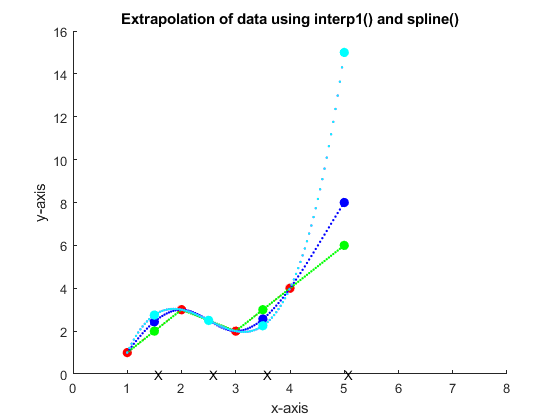

newx = linspace(1,5,100);
newyI = spline(x,y,newx); %Show extrapolation plot
plot(newx, newyI, 'c.', 'markersize', 5);     